# Polynomial Methods and Linear Regression

% Tutorial 2 covering Newton Polynomial Methods and Linear Regression

#### Question 1

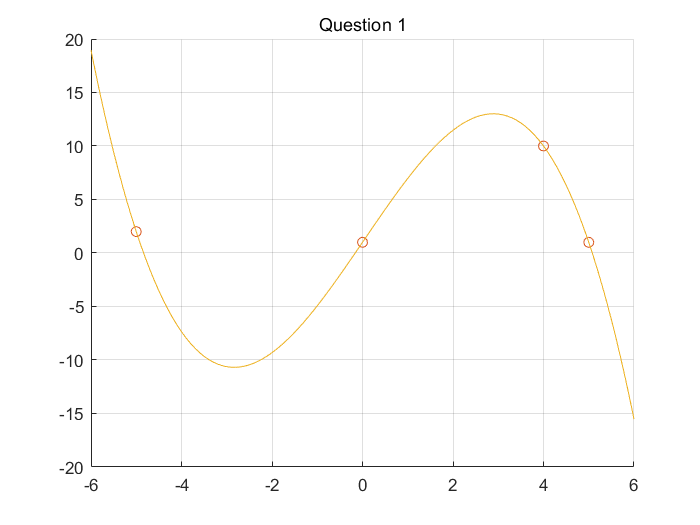

clear
x = [-5 0 4 5];
y = [2 1 10 1];
figure (1)
scatter(x,y);
hold on
i = -6:0.1:6;
l = length(i);
for t = 1:1:l
    yi(t) = NewtonPoly(x,y,i(t));
end
plot(i,yi);
title('Question 1');
grid on

hold off

#### Question 2 

clear
x = [-5 0 5 10];
y = [10.1 3.5 -1.2 -6.8];

mean_x = mean(x); %calculate the mean value of x
mean_y = mean(y); %calculate the mean value of y
St = sum((y-mean_y).^2) %calculate the sum of squared deviations

St =                      154.1


y_hat = 3.1-x;
Sr = sum((y-y_hat).^2) %calculate the sum of squares of the errors

Sr =                       4.66


R2 = 1 - Sr/St %coefficient of determination

R2 =          0.969759896171317


Syx = sqrt(Sr/(length(x)-2))  %standard Error of Estimate

Syx =           1.52643375224737


#### Question 2 bias

x = [1 3 11 13];
y = [-1 3 17 21];
y_hat1 = -2+x;
y_hat2 = -3+2*x;
mean_x = mean(x);
mean_y = mean(y);
St = sum((y-mean_y).^2) %calculate the sum of squared deviations

St =    340


Sr1 = sum((y-y_hat1).^2) %calculate the sum of squares of the errors of model1

Sr1 =    168


Sr2 = sum((y-y_hat2).^2) %calculate the sum of squares of the errors of model2

Sr2 =      8


mse_1=Sr1/length(x) %calculate the MSE of Model 1

mse_1 =     42


mes_2=Sr2/length(x) %Calculate the MSE of Model 2

mes_2 =      2


scatter(x,y);

R2_1 =          0.505882352941176


R2_2 =          0.976470588235294


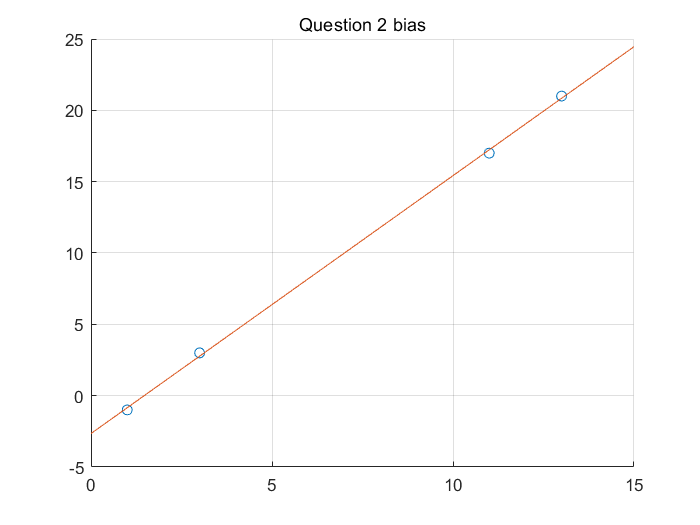

hold on
beta = sum((x-mean_x).*(y-mean_y))/sum((x-mean_x).^2);
alpha = mean_y-beta*mean_x;
t=0:0.1:15;
yt = alpha+beta*t;
plot(t,yt)
title('Question 2 bias');
grid on;
hold off;

#### Question 3